## MARTELET Curtis - YIN Zeyu

Pour un réglage compris entre 50 et 60 sur l'atténuateur, le signal devient difficilement perceptible. En équivalence wifi, cette atténuation correspond à une distance avec la source de moins de 10m.

Si l'on amplifie le signal avec un gain supérieur à 1, on devrait pouvoir augmenter la portée.

Selon la position de l'amplificateur sur la table, le signal dans le domaine des fréquences varie énormément. A environ 3Hz, un pic se forme (+- grand) quand on s'approche de l'ordinateur ou des générateurs.

On peut observer que la boite en aluminium que l'on positionne à l'INPUT isole des champs environnant : que l'on soit près ou loin des générateurs/appareils électriques, le pic que l'on avait avant n'est plus. C'est une cage de Faraday.

A partir de maintenant, nous utiliserons cette boite pour chaque prise de mesure pour obtenir les valeurs les plus précises possibles.

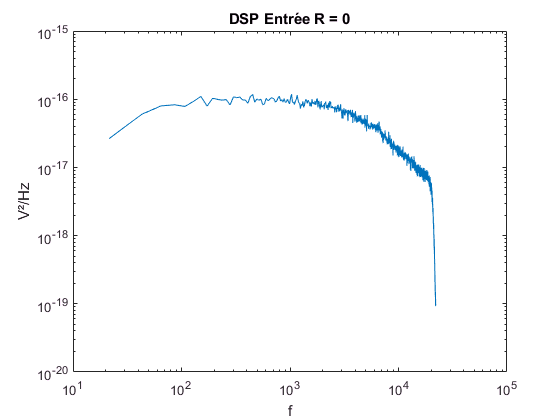

data0 = importdata('Amp0.tsv');
G = 53400;

f0 = data0(:,3);
h0 = data0(:,4)./(G^2);

loglog(f0,h0)
xlabel('f')
ylabel('V²/Hz')
title('DSP Entrée R = 0')

En fréquence, le signal log-log ressemble au bode d'un filtre passe-bas.

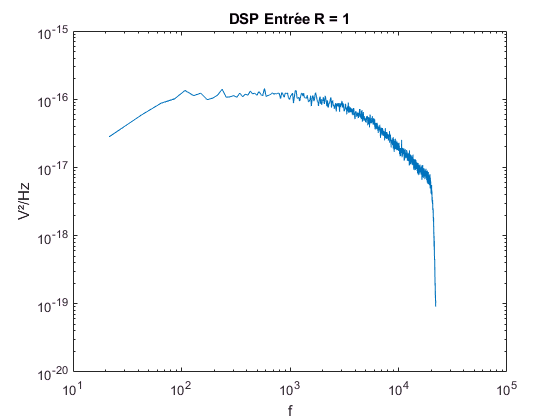

data1 = importdata('1kohm.tsv');
data11 = importdata('11kohm.tsv');
data22 = importdata('22kohm.tsv');
data33 = importdata('33kohm.tsv');

f1 = data1(:,3);
h1 = data1(:,4)./(G^2);
loglog(f1,h1)
xlabel('f')
ylabel('V²/Hz')
title('DSP Entrée R = 1')

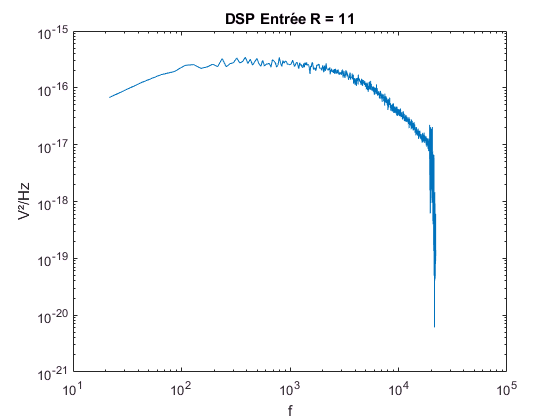

f11 = data11(:,3);
h11 = data11(:,4)./(G^2);
loglog(f11,h11)
xlabel('f')
ylabel('V²/Hz')
title('DSP Entrée R = 11')

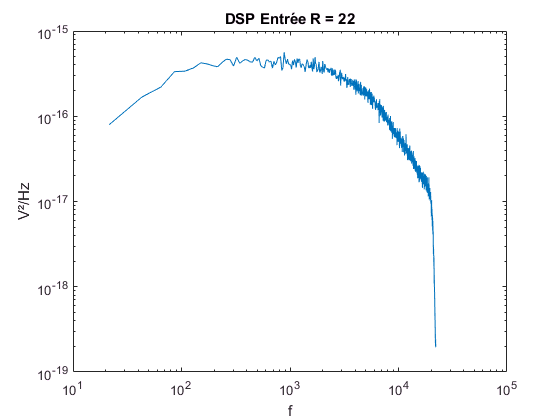

f22 = data22(:,3);
h22 = data22(:,4)./(G^2);
loglog(f22,h22)
xlabel('f')
ylabel('V²/Hz')
title('DSP Entrée R = 22')

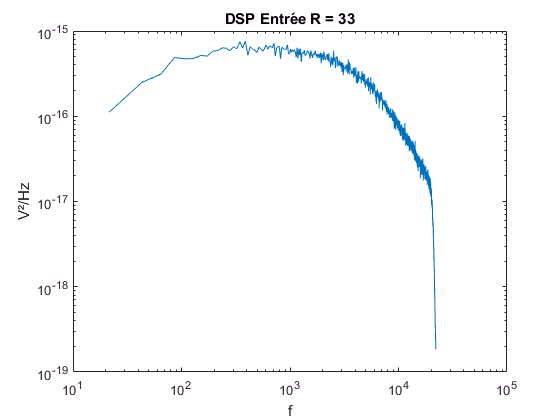

f33 = data33(:,3);
h33 = data33(:,4)./(G^2);
loglog(f33,h33)
xlabel('f')
ylabel('V²/Hz')
title('DSP Entrée R = 33')

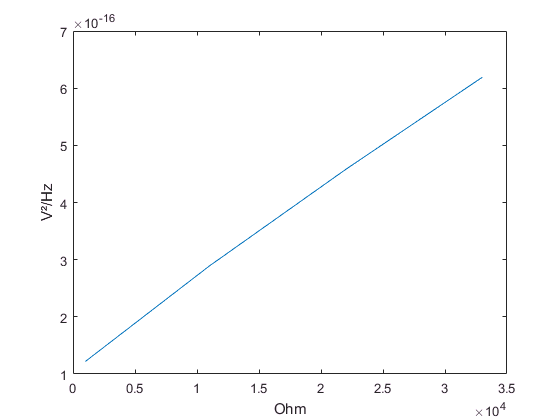

R = [1e3 11*1e3 22*1e3 33*1e3];
Plateau = [1.22*1e-16 2.89*1e-16 4.58*1e-16 6.19*1e-16];
plot(R,Plateau)
xlabel('Ohm')
ylabel('V²/Hz')

P = polyfit(R,Plateau,1) % Format ax+b

P =    1.5504e-20   1.1231e-16


Constante de Boltzmann: k

Sv = 4*k*T*R <=> k = Sv/(4*T*R)

T = 300K.

k=1.5504e-20/(4*300) % J/K

k =     1.292e-23


L'ordonnée à l'origine correspond au bruit pour une résistance nulle (court-circuit).

figure
loglog(f1,h1-P(2))
hold on

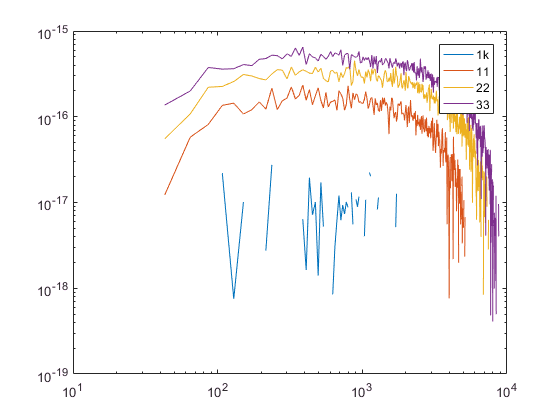

loglog(f11,h11-P(2))
hold on
loglog(f22,h22-P(2))
hold on
loglog(f33,h33-P(2))
legend('1k','11','22','33')

% yline(4*300*1e3*k,'-','Bruit 1k')
% yline(4*300*11e3*k,'-','Bruit 11k')
% yline(4*300*22e3*k,'-','Bruit 22k')
% yline(4*300*33e3*k,'-','Bruit 33k')